# Mini Project 2 - Meagan and Emma

## Calibration

%Calibration data and variables
load Calibration_data.csv
seveninch = mean(Calibration_data(:,2));
teninch = mean(Calibration_data(:,4));
twelveinch = mean(Calibration_data(:,6));
twentyfourinch = mean(Calibration_data(:,8));
thirtysixinch = mean(Calibration_data(:,10));
fourtyeightinch = mean(Calibration_data(:,12));
fiftyfourinch = mean(Calibration_data(:,14));

%Calibration testing data and variables
load Test_Calibration_data_part_two.csv
load Calibration_data_18.csv

Error using load
Unable to read file 'Calibration_data_18.csv'. Input must be a MAT-file or an ASCII file containing numeric data with same number of columns in each row.

fourtyinch = mean(Test_Calibration_data_part_two(:,2));
eighteeninch = mean(Calibration_data_18(:,2));

%data for finding line of best fit
bestfitx = [7,10,12,24,36];
bestfity = [seveninch, teninch, twelveinch, twentyfourinch, thirtysixinch];

%equation from line of best fit: y = (7362)./(x+6.488)
p1 = 7362;
q1 = 6.488;

%graph of data and line of best fit
figure(1)
clf; hold on
fplot(@(x) (p1)./(x+q1))
scatter(7, seveninch, 'b', 'filled')
scatter(18, eighteeninch, 'r', 'filled')
scatter(10, teninch, 'b', 'filled')
scatter(12, twelveinch, 'b', 'filled')
scatter(24, twentyfourinch, 'b', 'filled')
scatter(36, thirtysixinch, 'b', 'filled')
scatter(40, fourtyinch, 'r', 'filled')

xlabel("Distance (in)")
xlim([0 40])
ylabel("8-bit Output")
title("Calibration Curve")
legend('Calibration Curve', 'Values Used to Create Curve', 'Test Values')

% these two were measured for calibration, but have been excluded because
% they appear to be outside the sensor's accurate range
% scatter(48, fourtyeightinch)
% scatter(54, fiftyfourinch)

## 2D Scan

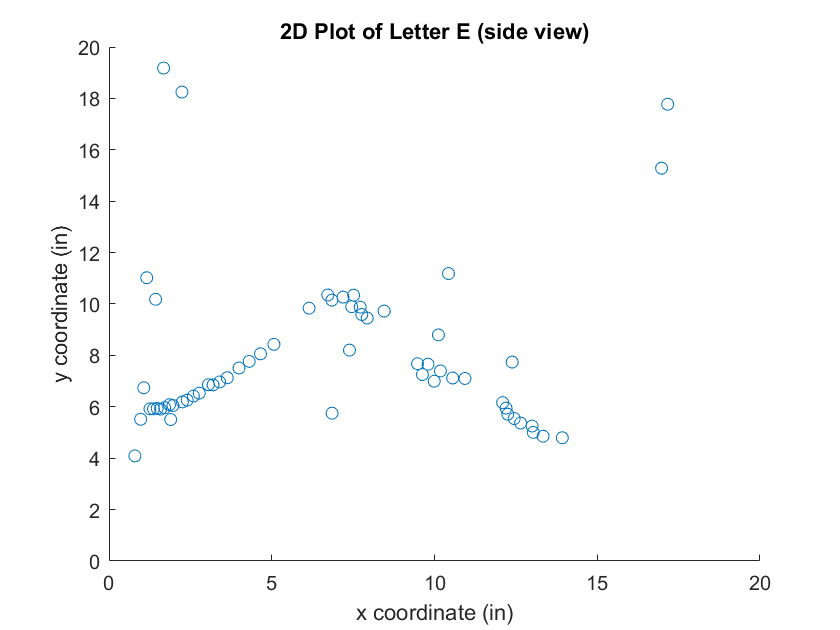

%load data and variables
load TwoDScanOne.csv
rho = TwoDScanOne(:,1); %vertical angle
rho = deg2rad(rho);
bit_distance = TwoDScanOne(:,2); %distance as an 8-bit output

%convert from 8-bit output to distance using y = (7362)./(x+6.488)
% --> x = 7362/y - 6.488
distance = 7362./bit_distance - 6.488; %inches

%create 2D plot
figure
clf; hold on
[x,y] = pol2cart(rho,distance);
plot(x,y,"o");
xlabel('x coordinate (in)')
ylabel('y coordinate (in)')
xlim([0 20])
ylim([0 20])
title('2D Plot of Letter E (side view)')

## 3D Scan

%load data and variables
load ThreeDDataOne.csv
theta = ThreeDDataOne(:,1); %horizontal angle
theta = deg2rad(theta);
rho = ThreeDDataOne(:,2); %vertical angle
rho = deg2rad(rho);
bit_distance = ThreeDDataOne(:,3); %distance as an 8-bit output

%convert from 8-bit output to distance using y = (7362)./(x+6.488)
% --> x = 7362/y - 6.488
distance = 7362./bit_distance - 6.488; %inches

%convert to Cartesian and plot
[x,y,z] = sph2cart(theta, rho, distance);

%create heatmap
n_bins = 81; % Number of grid cells
x_discrete = discretize(x, n_bins);
y_discrete = discretize(y, n_bins);
z_discrete = discretize(z, n_bins);
T1 = table(x_discrete,y_discrete,z_discrete);

%plot heatmap
figure
heat = heatmap(T1,"x_discrete","y_discrete","ColorVariable","z_discrete")

heat =   HeatmapChart (Mean of z\_discrete) with properties:

      SourceTable: [8180×3 table]
        XVariable: 'x_discrete'
        YVariable: 'y_discrete'
    ColorVariable: 'z_discrete'
      ColorMethod: 'mean'

  Show all properties


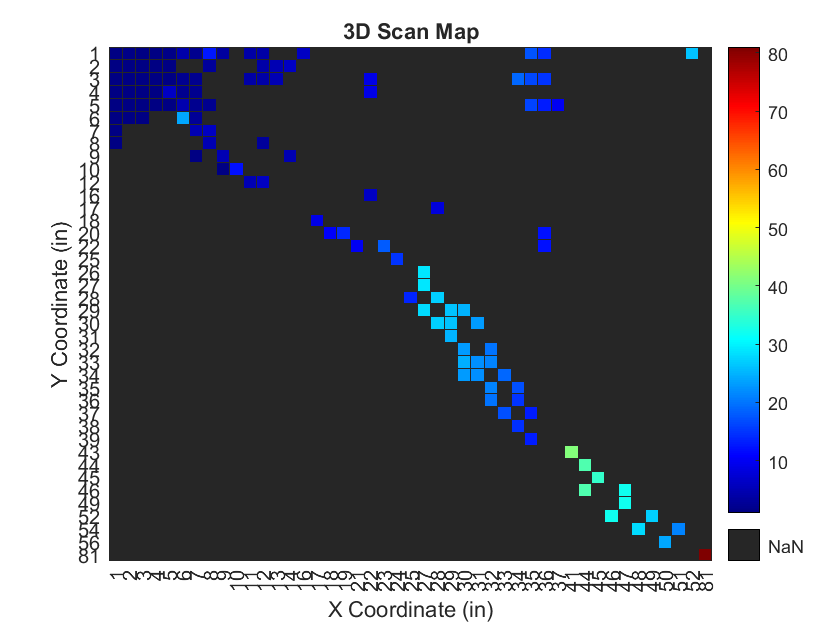

xlabel('X Coordinate (in)')
ylabel('Y Coordinate (in)')
title('3D Scan Map')
heat.Colormap = jet;

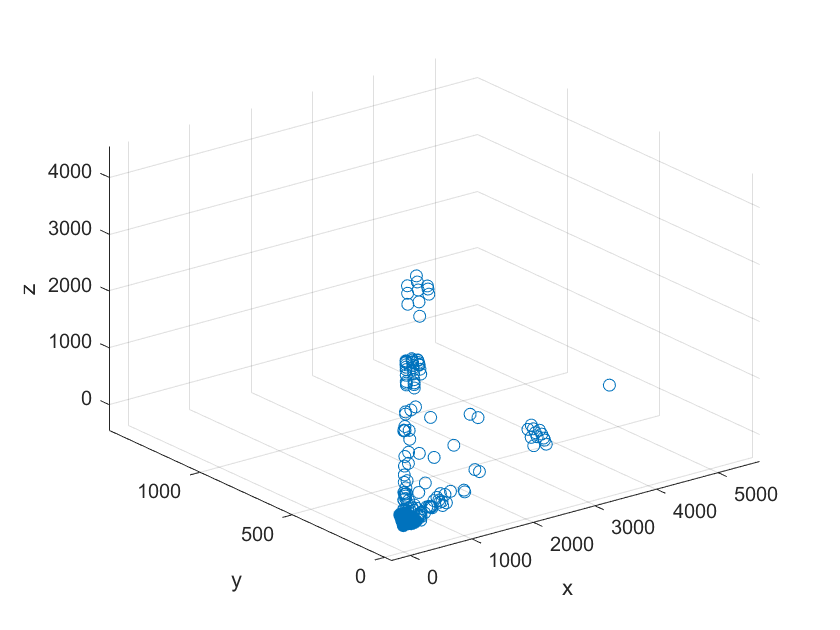


%plot 3D scatter
scatter3(x(1:2000,1),y(1:2000,1),z(1:2000,1));
xlabel('x');
ylabel('y');
zlabel('z');

%check with Arla's data
load ThreeDDataOne.csv

theta = ThreeDDataOne(:,1); %horizontal angle
theta = deg2rad(theta);
rho = ThreeDDataOne(:,2); %vertical angle
rho = deg2rad(rho);
bit_distance = ThreeDDataOne(:,3); %distance in volts
distance = 7362./bit_distance - 6.488; %inches

n_bins = 50; % Number of grid cells
[x,y,z] = sph2cart(theta, rho, distance);
x_discrete = discretize(x, n_bins);
y_discrete = discretize(y, n_bins);
z_discrete = discretize(z, n_bins);
T2 = table(x_discrete,y_discrete,z_discrete);
%T2 = table(x,y,z);

figure
heat = heatmap(T2,"x_discrete","y_discrete","ColorVariable","z_discrete")

heat =   HeatmapChart (Mean of z\_discrete) with properties:

      SourceTable: [8180×3 table]
        XVariable: 'x_discrete'
        YVariable: 'y_discrete'
    ColorVariable: 'z_discrete'
      ColorMethod: 'mean'

  Show all properties


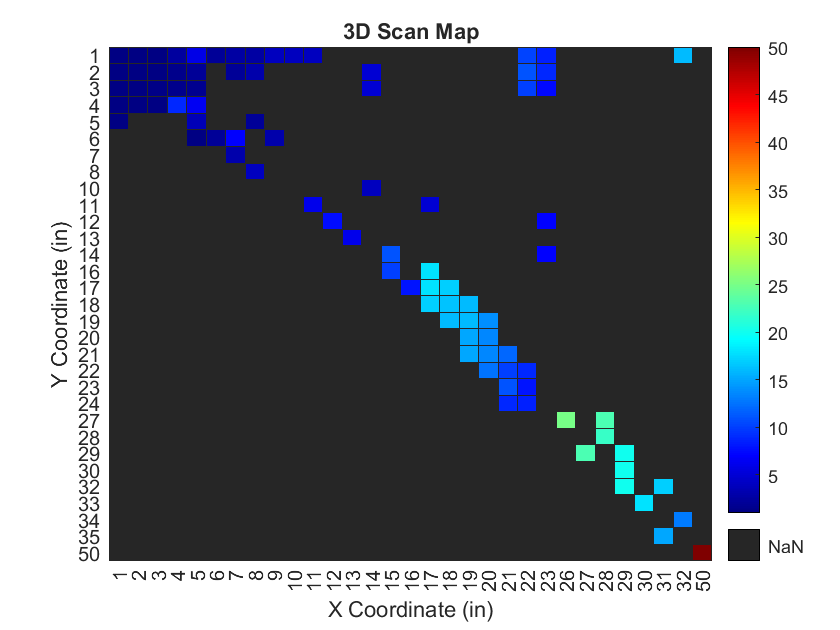

%heat = heatmap(T2,"x","y","ColorVariable","z")
xlabel('X Coordinate (in)')
ylabel('Y Coordinate (in)')
title('3D Scan Map')
heat.Colormap = jet;

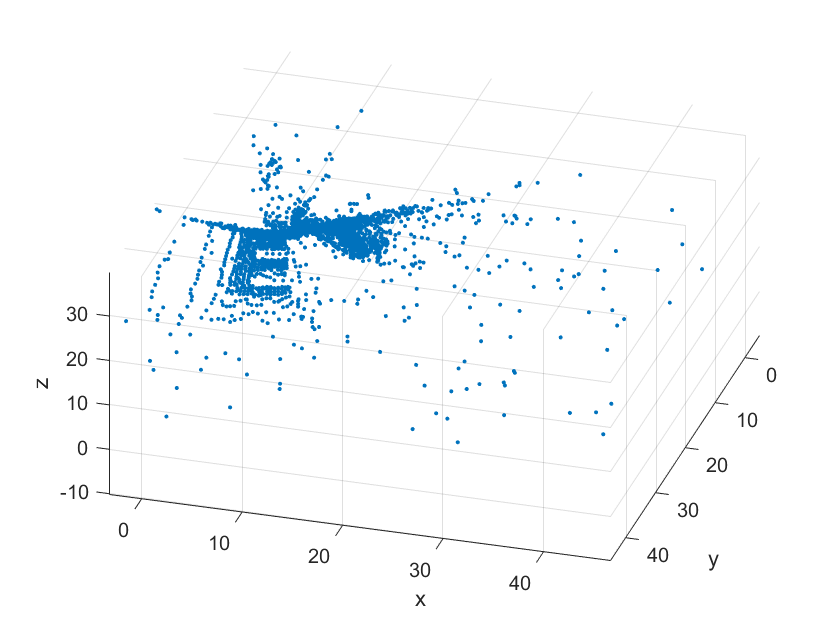


scatter3(x,y,z,'.');
xlabel('x');
ylabel('y');
zlabel('z');

xlim([0 50])
ylim([0 50])
zlim([0 50])